# WP5

Nota: prima di eseguire il codice assicurarsi di aver impostato come working directory di MATLAB la cartella "WP5".

## Parametri costanti

clear all 
clc

p1 = 0.0151; %tasso base di rimozione del glucosio dal sangue
p2 = 0.0313; %tasso rimozione del glucosio dovuto all'insulina
p3 = 0.0097;
ge = 0.97;
ie = 0.003;
u_eq = 1.003;

%x1 concentrazione del glucosio
%x2 concentrazione di insulina nei liquidi interstiziali 


## Controllore PI con $\sigma =r$

Per progettare un controllore basato su gain scheduling bisogna fare due scelte fondamentali:

- La variabile di scheduling $\sigma$ da utilizzare per scegliere i guadagni dei controllori

- Quale tipologia di controllori utilizzare per controllare le linearizzazioni del sistema attorno ai trim points

Un primo tentativo di progettazione è stato fatto scegliendo come variabile di scheduling $\sigma =r$ e come controllori lineari dei PI.

Consideriamo il sistema non lineare a ciclo aperto e troviamone i punti di equilibrio in funzione di u:

syms x1 x2 u
dx1 = -(p1+x2)*x1+p1*ge;
dx2 = -(p2*x2)+p3*(u-ie);

sol = solve([dx1==0, dx2==0],[x1, x2]);

Il nostro obiettivo è fare in modo che all'equilibrio sia $y_{\textrm{eq}} =r$. Siccome $y=x_1$ linearizziamo il sistema attorno a $\left(x_{1,\textrm{eq}} ,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)$ ponendo $x_{1,\textrm{eq}} =r=\sigma$ e trovando $x_{2,\textrm{eq}}$ e $u_{\textrm{eq}}$ in funzione di $\sigma$. 

syms sigma 
sol = solve([x1==sol.x1(1), x2==sol.x2(1), x1==sigma],[x1, x2, u]); %Qui poinamo x1_eq==sigma e troviamo x1_eq, x2_eq e u_eq in funzione di sigma
x1_eq = sol.x1(1);
x2_eq = sol.x2(1);
u_eq = sol.u(1);

Troviamo le matrici del sistema linearizzato in funzione di sigma, calcolando le Jacobiane e sostituendoci la condizione operativa che corrisponde al punto di equilibrio $\left(x_{1,\textrm{eq}} ,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)$

J_A=jacobian([dx1, dx2],[x1, x2]);
J_B=jacobian([dx1, dx2], u);
A = subs(J_A,{'x1','x2'}, [x1_eq, x2_eq]), B = J_B, C = [1 0]

$$A = \left(\begin{array}{cc} \frac{1360087087465889792\,\sigma -1319284474841913125}{90071992547409920000\,\sigma }-\frac{151}{10000} & -\sigma \\ 0 & -\frac{313}{10000} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ \frac{97}{10000} \end{array}\right)$$

C =      1     0


W_R=[B A*B A*A*B; 0 C*B C*A*B];
rank_WR = rank(W_R)

rank_WR = 3

Il rango della matrice di raggiungibilità (estesa con l'azione integrale) è pieno dunque il sistema è raggiungibile. Progettiamo un PI per il sistema linearizzato. In questo caso utilizzamo una progettazione diretta nel dominio del tempo con la tecnica del pole placement.

syms kp ki
A_CC = [A-B*kp*C B*ki; C 0]; % Matrice dinamica a ciclo chiuso del sistema linearizzato con controllore

% Per trovare i valori di K utilizziamo il principio di uguaglianza dei
% polinomi imponendo una dinamica del secondo ordine con un certo zita e
% omega_n.
syms s zita w_n p
pol_coeff=charpoly(A_CC); 
desired_pol=(s^2 + 2*zita*w_n*s + w_n^2)*(s-p);
desired_pol_coeff = fliplr(coeffs(desired_pol, s));

sol = solve(pol_coeff==desired_pol_coeff,[kp, ki],"ReturnConditions",true)

sol = struct with fields:
            kp: [0×1 sym]
            ki: [0×1 sym]
    parameters: [1×0 sym]
    conditions: [0×1 sym]


Non c'è soluzione al sistema di equazioni perché il secondo coefficiente del polinomio caratteristico non dipende dai parametri del controllore, allora non possiamo imporre una qualsiasi dinamica desiderata a ciclo chiuso utilizzando un PI. Tuttavia possiamo trovare i parametri del controllore che ci permettono di stabilizzare il sistema. Per farlo dobbiamo imporre che non ci siano variazioni di segno nei coefficienti del polinomio caratteristico:

assume(sigma>0);
sol = solve(pol_coeff>[0 0 0 0], [kp, ki],"ReturnConditions",true)

sol = struct with fields:
            kp: x
            ki: y
    parameters: [x    y]
    conditions: x < 660697665000830093/(13979173243358019584*sigma^2) & 0 < y


La soluzione è $k_i >0,k_p <\frac{0\ldotp 0473}{\sigma {\;}^2 }$. Ad esempio scegliendo ki = 1, kp = 0.03/sigma^2 si otterrebbe un sistema stabile a ciclo chiuso.

Per provare il controllore ottenuto in simulazione usare il seguente file simulink dopo aver eseguito la sezione superiore:

open_system('v3_sim_pi_sigma_r.slx')

Tale file contiene già diversi riferimenti. Tuttavia, non avendo potuto imporre una dinamica desiderata scartiamo questo controllore in favore dei successivi.

## Controllore state feedback con $\sigma =r$

Un secondo tentativo di progettazione è stato fatto scegliendo ancora come variabile di scheduling $\sigma =r$ e dei controllori basati su retroazione di stato. L'idea è che questi permettano di superare i limiti del PI potendo quindi imporre la dinamica del sistema a ciclo chiuso.

Consideriamo il sistema non lineare a ciclo aperto e troviamone i punti di equilibrio in funzione di u:

syms x1 x2 u
dx1 = -(p1+x2)*x1+p1*ge;
dx2 = -(p2*x2)+p3*(u-ie);

sol = solve([dx1==0, dx2==0],[x1, x2]);


Il nostro obiettivo è fare in modo che all'equilibrio sia $y_{\textrm{eq}} =r$. Siccome $y=x_1$ linearizziamo il sistema attorno a $\left(x_{1,\textrm{eq}} ,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)$ ponendo $x_{1,\textrm{eq}} =r=\sigma$ e trovando $x_{2,\textrm{eq}}$ e $u_{\textrm{eq}}$ in funzione di $\sigma$.

syms sigma 
%Qui poinamo x1_eq==sigma e troviamo x2_eq e u_eq in funzione di sigma
sol = solve([x1==sol.x1(1), x2==sol.x2(1), x1==sigma],[x1, x2, u]);
x1_eq = sol.x1(1);
x2_eq = sol.x2(1);
u_eq = sol.u(1);

Troviamo le matrici del sistema linearizzato in funzione di sigma, calcolando le Jacobiane e sostituendoci la condizione operativa che corrisponde al punto di equilibrio $\left(x_{1,\textrm{eq}} ,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)$

J_A=jacobian([dx1, dx2],[x1, x2]);
J_B=jacobian([dx1, dx2], u);
A = subs(J_A,{'x1','x2'}, [x1_eq, x2_eq]), B = J_B, C = [1 0];

$$A = \left(\begin{array}{cc} \frac{1360087087465889792\,\sigma -1319284474841913125}{90071992547409920000\,\sigma }-\frac{151}{10000} & -\sigma \\ 0 & -\frac{313}{10000} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ \frac{97}{10000} \end{array}\right)$$

Adesso si passa alla progettazione dei controllori state feedback. Si devono calcolare i guadagni K del controllore in funzione di $\sigma$. Utilizziamo il metodo del pole placement, calcolando il polinomio caratteristico della matrice dinamica del sistema linearizzato retroazionato $A-\textrm{BK}$

syms k1 k2
K = [k1 k2];
A_CC = A-B*K; %Matrice dinamica a ciclo chiuso


Per trovare i valori di$K$utilizziamo il principio di uguaglianza dei polinomi imponendo una dinamica del secondo ordine con un certo $\zeta$ e $\omega_n$ simbolici e risolvendo il tutto per $k_1 ,k_2$.

% In questo caso troviamo i parametri K in funzione di sigma, zita e omega_n.
syms s zita w_n
pol_coeff=charpoly(A_CC); 
desired_pol=(s^2 + 2*zita*w_n*s + w_n^2);
desired_pol_coeff = fliplr(coeffs(desired_pol, s));
sol = solve(pol_coeff==desired_pol_coeff,[k1, k2],"ReturnConditions",true);
k1=sol.k1, k2=sol.k2

$$k1 = -\frac{625\,\left(20769187434139310514121985316880384\,\sigma^{2}\,{w_{n}}^{2}-608412576695676974541561223184384\,\mathrm{zita}\,\sigma \,w_{n}+4455709505430790413433498137721\right)}{125913198819469569991864535983587328\,\sigma^{3}}$$

$$k2 = -\frac{2819253366733930496\,\sigma -180143985094819840000\,\sigma \,w_{n}\,\mathrm{zita}+1319284474841913125}{873698327709876224\,\sigma }$$

La legge di controllo implementata per il sistema non lineare è quindi:


$$u = -\mathbf K (\mathbf x- \mathbf x_{eq})+u_{eq}$$


dove $u_{\textrm{eq}}$, ${\mathbf{x}}_{\textrm{eq}}$ e $\mathbf{K}$ sono calcolati dallo scheduler in funzione di $\sigma$ con le relazioni trovate. Osserviamo che il sistema viene linearizzato attorno al punto $\left(x_{1,\textrm{eq}} =r,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)$dunque per avere $y=x_1 =r$ a regime, il problema di controllo sul sistema linearizzato diventa un problema di regolazione sul punto $\delta \mathbf{x}=\left(0,0\right)$.

A questo punto si procede ad analizzare le prestazioni dei controllori trovati su

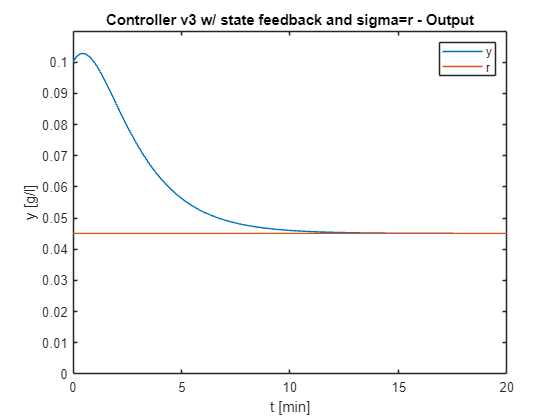

% Analisi delle prestazioni
simout = sim('v3_sim_sf_sigma_r.slx'); %Nel file simulink sono specificati i valori di zita e omega_n
y = simout.y;
t = simout.t;
u = simout.u(1,:);
figure;
plot(t, y)
xlim([0,20])
title('Controller v3 w/ state feedback and sigma=r - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,y(end))

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 9.6081
     SettlingTime: 10.0932
      SettlingMin: 0.0451
      SettlingMax: 0.1028
        Overshoot: 127.8867
       Undershoot: 0
             Peak: 0.1028
         PeakTime: 0.4358


Relativamente alla risposta del sistema, si osservi che:

- Non sono presenti sottoelongazioni

- Il tempo di assestamento è pari a $t_{s\;} =10\;\min$

- Non ha senso valutare il tempo di salita in quanto il riferimento è al di sotto dello stato iniziale

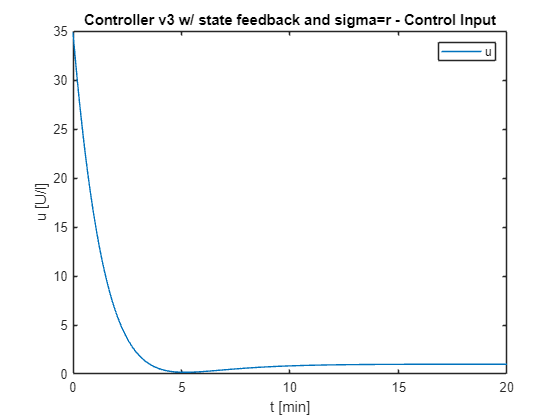

figure;
plot(t, u)
xlim([0,20])
title('Controller v3 w/ state feedback and sigma=r - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 6.4261
     SettlingTime: 14.5099
      SettlingMin: 0.1756
      SettlingMax: 34.8425
        Overshoot: 3.3765e+03
       Undershoot: 0
             Peak: 34.8425
         PeakTime: 0


u_max = max(u), u_min = min(u)

u_max = 34.8425

u_min = 0.1756

Per quanto riguarda l'ingresso di controllo:

- L'ingresso ha come picco massimo 34.85 U/l, più di 2500 volte inferiore rispetto all'ingresso fornito dal controllore v0;

- L'ingresso non assume valori negativi pertanto non è affetto dai fenomeni di saturazione.

Come prevedibile le prestazioni sono del tutto analoghe a quelle ottenute con lo stesso controllore nel WP2.

Per ulteriori simulazioni con riferimenti tempo varianti fare riferimento al seguente file Simulink:

open_system('v3_sim_sf_sigma_r.slx')

## Controllore state feedback con $\sigma =x_1$

A questo punto si è fatto un tentativo progettando controllori state feedback scegliendo come variabile di scheduling $\sigma =x_1$ anziché r. La procedura di progettazione dei controllori è analoga a quella seguita nella sezione precedente. La legge di controllo implementata per il sistema non lineare è:


$$u = -\mathbf K (\mathbf x- \mathbf x_{eq})+K_r (r-y
) +u_{eq}$$


dove $u_{\textrm{eq}}$, ${\mathbf{x}}_{\textrm{eq}}$, $\mathbf{K}$ e $K_r$ sono calcolati dallo scheduler in funzione di $\sigma$. Il termine aggiuntivo $K_r \left(r-y\right)$ rispetto al caso $\sigma =r$ serve perché in questo caso il sistema è linearizzato attorno al punto $\left(x_{1,\textrm{eq}} =\sigma ,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)\;$e in generale $\sigma =x_1 \not= r$, dunque per avere $y=x_1 =r$ a regime, in questo caso il problema di controllo sul sistema linearizzato diventa un problema di regolazione dello stato sul punto $\delta \mathbf{x}=\left(\delta x_1 =r-y,\delta x_2 \right)$.

Di seguito ne riportiamo i risultati in simulazione:

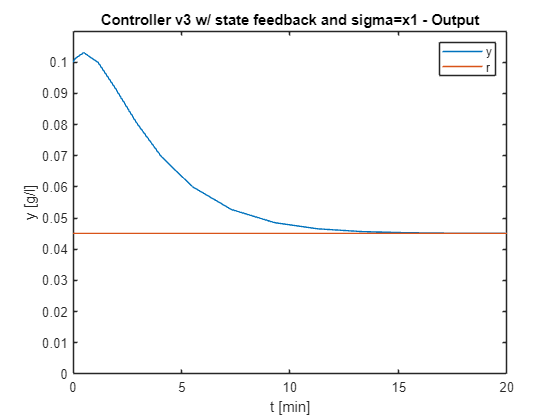

% Analisi delle prestazioni
simout = sim('v3_sim_sf_sigma_x1.slx'); %Nel file simulink sono specificati i valori di zita e omega_n
y = simout.y;
t = simout.t;
u = simout.u(1,:);
figure;
plot(t, y)
xlim([0,20])
title('Controller v3 w/ state feedback and sigma=x1 - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')

legend('y','r')

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 11.9585
     SettlingTime: 12.5541
      SettlingMin: 0.0451
      SettlingMax: 0.1031
        Overshoot: 128.5671
       Undershoot: 0
             Peak: 0.1031
         PeakTime: 0.4938


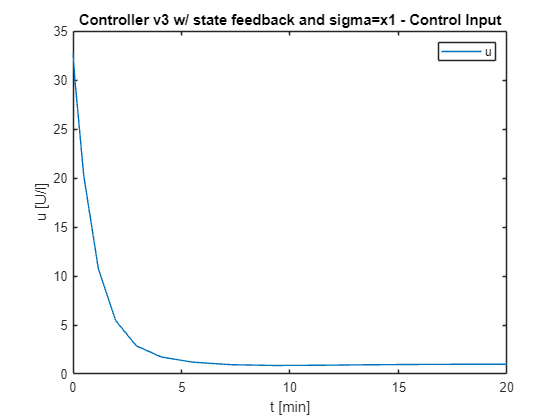

ylim([0 0.11])
y_stepinfo = stepinfo(y,t,y(end))
figure;
plot(t, u)
xlim([0,20])
title('Controller v3 w/ state feedback and sigma=x1 - Control Input')
ylabel('u [U/l]')

xlabel('t [min]')

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 4.3265
     SettlingTime: 16.6568
      SettlingMin: 0.8691
      SettlingMax: 32.7691
        Overshoot: 3.1696e+03
       Undershoot: 0
             Peak: 32.7691
         PeakTime: 0


legend('u')

u_max = 32.7691

u_min = 0.8691

u_stepinfo = stepinfo(u,t,u(end))
u_max = max(u), u_min = min(u)

Le prestazioni sono simili al caso precedente ma con un tempo di assestamento superiore.

Per ulteriori simulazioni con diversi riferimenti fare riferimento al seguente file Simulink:

open_system('v3_sim_sf_sigma_x1.slx')

Entrambi i controllori non hanno performance tanto buone quanto quelle del controllore scelto nel WP2. Dunque si è proceduto dapprima col progettare dei controllori LQR e poi con la progettazione di controllori LQI.

## Controllore LQR con $\sigma =r$

A questo punto per tentare di ottenere performance migliori si vuole progettare un controllore LQR per ciascuno dei trim points utilizzando gli stessi pesi utilizzati nel WP2.

% Consideriamo il sistema non lineare a ciclo aperto
syms x1 x2 u
dx1 = -(p1+x2)*x1+p1*ge;
dx2 = -(p2*x2)+p3*(u-ie);
% Troviamone i punti di equilibrio al variare di u_eq
sol = solve([dx1==0, dx2==0],[x1, x2],"ReturnConditions",true);


Il nostro obiettivo è fare in modo che all'equilibrio sia $y_{\textrm{eq}} =r$. Siccome $y=x_1$ linearizziamo il sistema attorno a $\left(x_{1,\textrm{eq}} ,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)$ ponendo $x_{1,\textrm{eq}} =r=\sigma$ e trovando $x_{2,\textrm{eq}}$ e $u_{\textrm{eq}}$ in funzione di $\sigma$.

syms sigma 
% Qui poniamo x1_eq==sigma e troviamo x2_eq e u_eq in funzione di sigma
sol = solve([x1==sol.x1(1), x2==sol.x2(1), x1==sigma],[x1, x2, u],"ReturnConditions",true); 
x1_eq = sol.x1(1)

$$x1\_eq = \sigma$$

x2_eq = sol.x2(1)

$$x2\_eq = -\frac{1360087087465889792\,\sigma -1319284474841913125}{90071992547409920000\,\sigma }$$

u_eq = sol.u(1)

$$u\_eq = -\frac{399496308545527218176\,\sigma -412936040625518808125}{8736983277098762240000\,\sigma }$$

Troviamo le matrici del sistema linearizzato in funzione di sigma, calcolando le Jacobiane e sostituendoci la condizione operativa che corrisponde al punto di equilibrio $\left(x_{1,\textrm{eq}} ,x_{2,\textrm{eq}} ,u_{\textrm{eq}} \right)$

J_A=jacobian([dx1, dx2],[x1, x2]);
J_B=jacobian([dx1, dx2], u);
A = subs(J_A,{'x1','x2'}, [x1_eq, x2_eq]),B = double(J_B),C = [1 0],D=0

$$A = \left(\begin{array}{cc} \frac{1360087087465889792\,\sigma -1319284474841913125}{90071992547409920000\,\sigma }-\frac{151}{10000} & -\sigma \\ 0 & -\frac{313}{10000} \end{array}\right)$$

B =          0
    0.0097


C =      1     0


D = 0

Adesso per ciascuno dei trim points si calcolano i guadagni K del controllore LQR e si salvano i risultati nel vettore K_sigma che contiene su ogni colonna j il valore dei guadagni associati alla condizione operativa $\sigma_j =0\ldotp 01+0\ldotp 02\left(j-1\right)$ (le condizioni considerate sono nel range $\sigma \in \left\lbrack 0\ldotp 01,2\right\rbrack$).

sigma = [0.01:0.02:2];
K_sigma = [];

for i = sigma
    temp_A = double(subs(A,{'sigma'},i));
    sys = ss(temp_A,B,C,D);
    % I parametri dell'LQR sono gli stessi di quelli trovati nel WP2
    Qu = 1e-4;
    Qx = [10 0;0 0.1];
    [K,S,P] = lqr(sys, Qx, Qu);
    K_sigma = [K_sigma, K.'];
    % K_sigma contiene su ogni colonna j il valore dei parametri associati 
    % alla condizione operativa sigma(j).
    % La prima riga contiene il parametro k1 e la seconda il parametro k2.
end
K_sigma

K_sigma =    -1.8669  -35.5189 -101.3700 -158.5216 -197.7134 -224.0753 -242.3379 -255.4529 -265.1875 -272.6217 -278.4384 -283.0841 -286.8607 -289.9776 -292.5844 -294.7898 -296.6748 -298.3007 -299.7143 -300.9524 -302.0439 -303.0120 -303.8752 -304.6487 -305.3450 -305.9744 -306.5457 -307.0659 -307.5413 -307.9771 -308.3777 -308.7470 -309.0883 -309.4045 -309.6980 -309.9712 -310.2258 -310.4637 -310.6862 -310.8949 -311.0908 -311.2750 -311.4484 -311.6120 -311.7665 -311.9126 -312.0509 -312.1819 -312.3063 -312.4244
   28.6207   31.8462   42.1104   54.2045   65.1788   74.8279   83.4108   91.1714   98.2899  104.8955  111.0820  116.9190  122.4595  127.7446  132.8068  137.6726  142.3635  146.8974  151.2893  155.5520  159.6966  163.7324  167.6679  171.5103  175.2660  178.9408  182.5398  186.0675  189.5281  192.9254  196.2627  199.5432  202.7698  205.9451  209.0714  212.1511  215.1861  218.1784  221.1297  224.0418  226.9161  229.7542  232.5573  235.3268  238.0638  240.7695  243.4450  246.0912  248.709

A questo punto si implementa lo stesso schema di controllo utilizzato nel WP2, con la differenza che i guadagni $\mathbf{K}$ sono interpolati dallo scheduler a partire dalla tabella ottenuta prima mentre i parametri $u_{\textrm{eq}\;}$e ${\mathbf{x}}_{\textrm{eq}}$ sono calcolati in tempo reale dallo scheduler.

Di seguito ne riportiamo i risultati in simulazione:

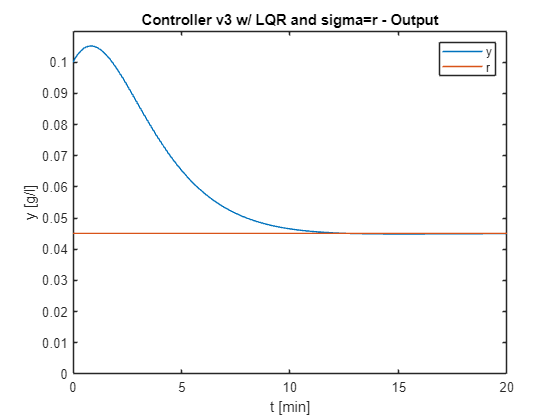

% Analisi delle prestazioni
simout = sim('v3_sim_lqr_sigma_r.slx');
y = simout.y;
t = simout.t;
u = simout.u;
figure;
plot(t, y)
xlim([0,20])
title('Controller v3 w/ LQR and sigma=r - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,y(end))

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 10.2472
     SettlingTime: 10.6075
      SettlingMin: 0.0449
      SettlingMax: 0.1052
        Overshoot: 133.2433
       Undershoot: 0
             Peak: 0.1052
         PeakTime: 0.8125


Osserviamo come l'assenza di sottoelongazioni e il tempo di assestamento di 10.5 min rendano le prestazioni di questa soluzione paragonabili a quella della retroazione di stato con $\sigma =r$.

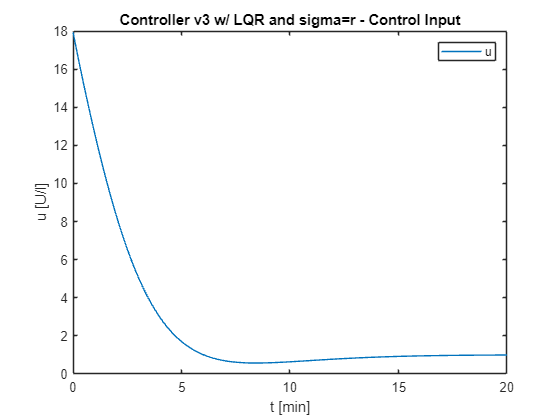

figure;
plot(t, u)
xlim([0,20])
title('Controller v3 w/ LQR and sigma=r - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 10.3410
     SettlingTime: 17.9563
      SettlingMin: 0.5760
      SettlingMax: 17.9432
        Overshoot: 1.6903e+03
       Undershoot: 0
             Peak: 17.9432
         PeakTime: 0


u_max = max(u), u_min = min(u)

u_max = 17.9432

u_min = 0.5760

In questo caso l'ingresso di controllo massimo è quasi dimezzato rispetto alle soluzioni precedenti. Inoltre gli ingressi di controllo sono sempre positivi dunque il controllore non risentirà degli effetti di saturazione (nel task di regolazione proposto). Dunque questa soluzione è la migliore tra quelle fin ora trovate. 

Per ulteriori simulazioni con riferimenti tempo varianti fare riferimento al seguente file Simulink:

open_system('v3_sim_lqr_sigma_r.slx')

A questo punto però per migliorare le performance rispetto a riferimenti tempo varianti e garantire reiezione dei disturbi si decide di introdurre l'azione integrale tramite LQI, analogamente a quanto fatto nel WP2.

## Controllore LQI con $\sigma =r$ 

A questo punto si seguono i passi progettuali della sezione precedente progettando per ogni trim point un controllore LQI con gli stessi pesi scelti nel WP2.

% Consideriamo il sistema non lineare a ciclo aperto
syms x1 x2 u
dx1 = -(p1+x2)*x1+p1*ge;
dx2 = -(p2*x2)+p3*(u-ie);
% Troviamone i punti di equilibrio al variare di u_eq
sol = solve([dx1==0, dx2==0],[x1, x2],"ReturnConditions",true);

% Scegliamo come variabile di scheduling sigma=r.
% Il nostro obiettivo è che y_eq = r. Siccome y=x1 linearizziamo il sistema
% attorno a (x1_eq,x2_eq,u_eq) ponendo x1_eq = r = sigma e trovando x2_eq e 
% u_eq in funzione di sigma.
syms sigma 
% Qui poinamo x1_eq==sigma e troviamo x2_eq e u_eq in funzione di sigma
sol = solve([x1==sol.x1(1), x2==sol.x2(1), x1==sigma],[x1, x2, u],"ReturnConditions",true); 
x1_eq = sol.x1(1);
x2_eq = sol.x2(1);
u_eq = sol.u(1);

% Troviamo le matrici del sistema linearizzato in funzione di sigma,
% calcolando le Jacobiane e sostituendoci la condizione operativa che
% corrisponde al punto di equilibrio (x1_eq,x2_eq,u_eq)
J_A=jacobian([dx1, dx2],[x1, x2]);
J_B=jacobian([dx1, dx2], u);
A = subs(J_A,{'x1','x2'}, [x1_eq, x2_eq]);
B = double(J_B);
C = [1 0];
D=0;

% Adesso andiamo a calcolare i parametri K del controllore LQR nei trim
% points.
sigma = [0.01:0.02:2];
K_sigma = [];

for i = sigma
    temp_A = double(subs(A,{'sigma'},i));
    sys = ss(temp_A,B,C,D);
    %I parametri dell'LQI sono gli stessi trovati nel WP2
    Qu = 6e-6;
    Qx = [10 0 0;0 0.1 0;0 0 1];
    [K,S,e] = lqi(sys,Qx,Qu,0);
    K_sigma = [K_sigma, K.'];
    % K_sigma contiene su ogni colonna j il valore dei parametri associati 
    % alla condizione operativa sigma(j).
    % La prima riga contiene il parametro k1,la seconda il parametro k2, e
    % la terza il parametro ki
end

Di seguito si presentano i risultati in simulazione:

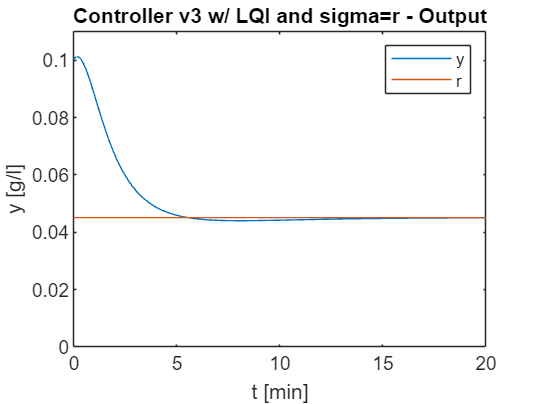

% Analisi delle prestazioni
simout = sim('v3_sim_lqi_sigma_r.slx');
y = simout.y;
t = simout.t;
u = simout.u;
figure;
plot(t, y)
xlim([0,20])
title('Controller v3 w/ LQI and sigma=r - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')

ylim([0 0.11])

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 4.8820
     SettlingTime: 9.4930
      SettlingMin: 0.0440
      SettlingMax: 0.1012
        Overshoot: 124.6604
       Undershoot: 0
             Peak: 0.1012
         PeakTime: 0.1990


y_stepinfo = stepinfo(y,t,y(end))

undershoot = 0.0239

undershoot=abs(min(y)-0.045102)/0.045102

È presente una sottoelongazione del 2% e il tempo di assestamento è di 10 min.

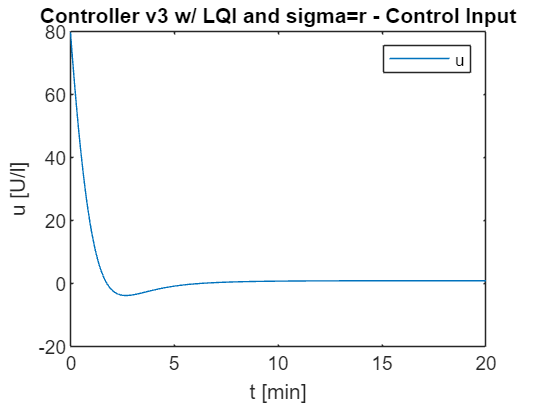

figure;
plot(t, u)
xlim([0,20])
title('Controller v3 w/ LQI and sigma=r - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 5.1654
     SettlingTime: 14.2035
      SettlingMin: -3.7030
      SettlingMax: 79.7531
        Overshoot: 7.8672e+03
       Undershoot: 369.9216
             Peak: 79.7531
         PeakTime: 0


u_max = max(u), u_min = min(u)

u_max = 79.7531

u_min = -3.7030

In questo caso l'ingresso di controllo massimo è pari a 80 U/l e il minimo ingresso di controllo è di -3.7 U/l, quindi il controllore non risentirà molto degli effetti di saturazione (nel task di regolazione proposto). 

Per ulteriori simulazioni con riferimenti tempo varianti fare riferimento al seguente file Simulink:

open_system('v3_sim_lqi_sigma_r.slx')

Questo controllore è considerato migliore del precedente in quanto grazie all'azione integrale ha migliori performance di inseguimento di riferimenti tempo varianti ed è in grado di rigettare disturbi a gradino, il tutto al costo di un piccolo peggioramento delle performance in termini di sforzo di controllo e sottoelongazione percentuale.

## Controllore LQI con $\sigma =x_1$ 

Infine, si è tentata la progettazione di un controllore LQI sui trim points scegliendo come variabile di scheduling $\sigma =x_1$. I passaggi relativi alla progettazione del controllore sono gli stessi seguiti nelle sezioni precedenti. Visualizziamone le performance rispetto al task di regolazione:

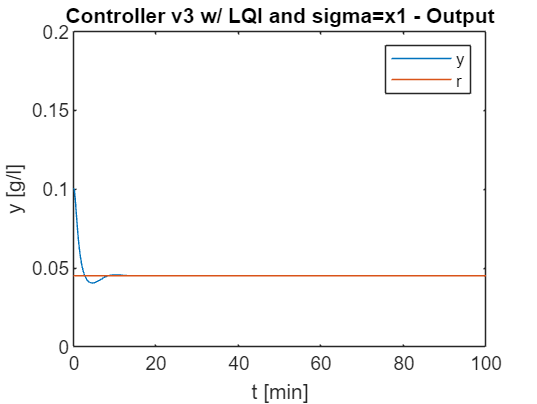

syms x1 x2 u
dx1 = -(p1+x2)*x1+p1*ge;
dx2 = -(p2*x2)+p3*(u-ie);
sol = solve([dx1==0, dx2==0],[x1, x2],"ReturnConditions",true);
syms sigma 
sol = solve([x1==sol.x1(1), x2==sol.x2(1), x1==sigma],[x1, x2, u],"ReturnConditions",true); 
x1_eq = sol.x1(1);
x2_eq = sol.x2(1);
u_eq = sol.u(1);
J_A=jacobian([dx1, dx2],[x1, x2]);
J_B=jacobian([dx1, dx2], u);
A = subs(J_A,{'x1','x2'}, [x1_eq, x2_eq]);
B = double(J_B);
C = [1 0];
D=0;
sigma = [0.01:0.02:2];
K_sigma = [];

for i = sigma
    temp_A = double(subs(A,{'sigma'},i));
    sys = ss(temp_A,B,C,D);
    Qu = 8e-6;
    Qx = [120 0 0;0 0.001 0;0 0 3];
    [K,S,e] = lqi(sys,Qx,Qu,0);
    K_sigma = [K_sigma, K.'];
end
% Analisi delle prestazioni
simout = sim('v3_sim_lqi_sigma_x1.slx');
y = simout.y;
t = simout.t;
u = simout.u;
figure;
plot(t, y)
xlim([0,100])
title('Controller v3 w/ LQI and sigma=x1 - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')

ylim([0 0.2])

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 7.4238
     SettlingTime: 7.5800
      SettlingMin: 0.0405
      SettlingMax: 0.1005
        Overshoot: 122.8154
       Undershoot: 0
             Peak: 0.1005
         PeakTime: 0.0823


y_stepinfo = stepinfo(y,t,y(end))

percentage_undershoot = 0.1018

percentage_undershoot = abs(min(y)-0.045102)/0.045102

Ulteriori risultati sperimentali sono visualizzabili tramite il seguente file Simulink:

open_system('v3_sim_lqi_sigma_x1.slx')

## Scelta del controllore e simulazioni per riferimenti tempo varianti

Dalle discussioni fatte in precedenza, il controllore scelto a valle del WP5 è quello basato su LQI con $\sigma =r$. Tale scelta è stata fatta anche sulla base delle prestazioni rispetto all'inseguimento di diversi riferimenti tempo varianti. Di seguito riportiamo alcune simulazioni fatte col controllore scelto e alcuni riferimenti tempo varianti:

syms x1 x2 u
dx1 = -(p1+x2)*x1+p1*ge;
dx2 = -(p2*x2)+p3*(u-ie);
sol = solve([dx1==0, dx2==0],[x1, x2],"ReturnConditions",true);

syms sigma 
sol = solve([x1==sol.x1(1), x2==sol.x2(1), x1==sigma],[x1, x2, u],"ReturnConditions",true); 
x1_eq = sol.x1(1);
x2_eq = sol.x2(1);
u_eq = sol.u(1);
J_A=jacobian([dx1, dx2],[x1, x2]);
J_B=jacobian([dx1, dx2], u);
A = subs(J_A,{'x1','x2'}, [x1_eq, x2_eq]);
B = double(J_B);
C = [1 0];
D=0;
sigma = [0.01:0.02:2];
K_sigma = [];

for i = sigma
    temp_A = double(subs(A,{'sigma'},i));
    sys = ss(temp_A,B,C,D);
    Qu = 6e-6; 
    Qx = [10 0 0;0 0.1 0;0 0 1];
    [K,S,e] = lqi(sys,Qx,Qu,0);
    K_sigma = [K_sigma, K.'];
end

### Rampe

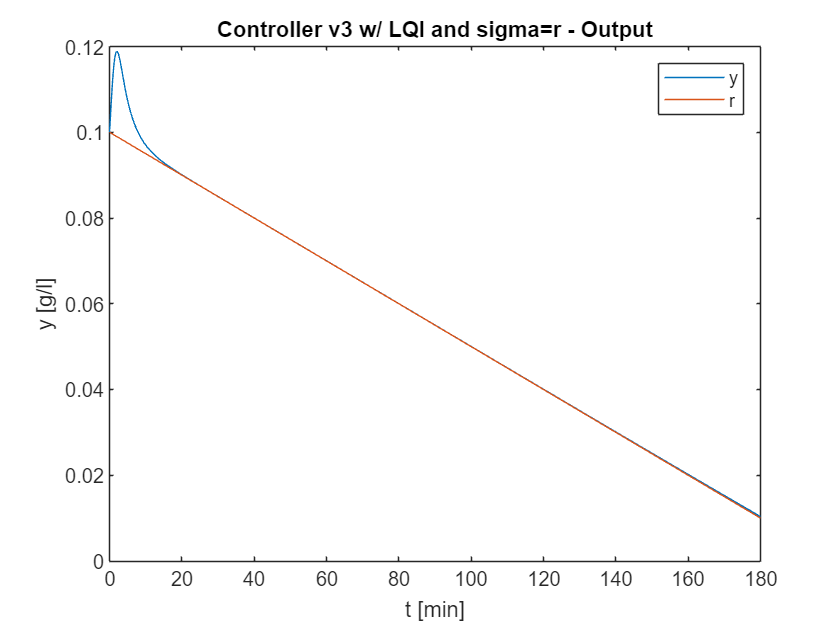

reference_selector=1;
simout = sim('v3_sim_lqi_sigma_r_time_variant.slx');
y = simout.y;
t = simout.t;
u = simout.u;
r = simout.r;
figure;
plot(t, y)
xlim([0,180])
title('Controller v3 w/ LQI and sigma=r - Output')
hold on
plot(t,r)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')

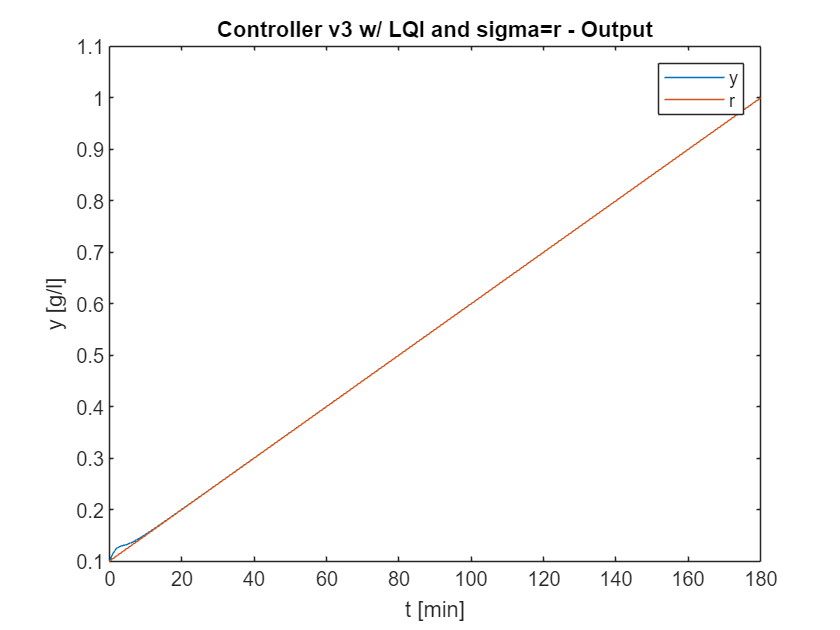

reference_selector=2;
simout = sim('v3_sim_lqi_sigma_r_time_variant.slx');
y = simout.y;
t = simout.t;
u = simout.u;
r = simout.r;
figure;
plot(t, y)
xlim([0,180])
title('Controller v3 w/ LQI and sigma=r - Output')
hold on
plot(t,r)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')

### Rampa discreta

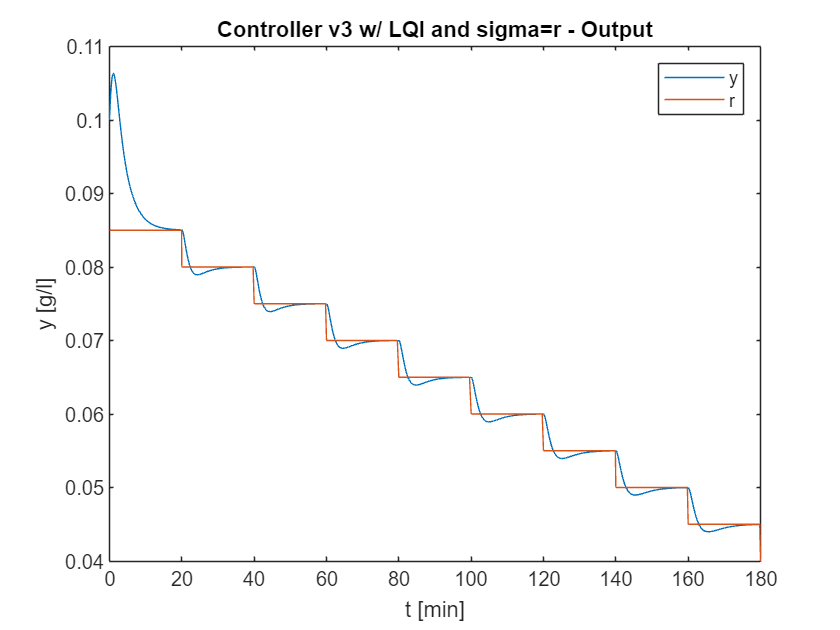

reference_selector=3;
simout = sim('v3_sim_lqi_sigma_r_time_variant.slx');
y = simout.y;
t = simout.t;
u = simout.u;
r = simout.r;
figure;
plot(t, y)
xlim([0,180])
title('Controller v3 w/ LQI and sigma=r - Output')
hold on
plot(t,r)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')

### Sinusoide

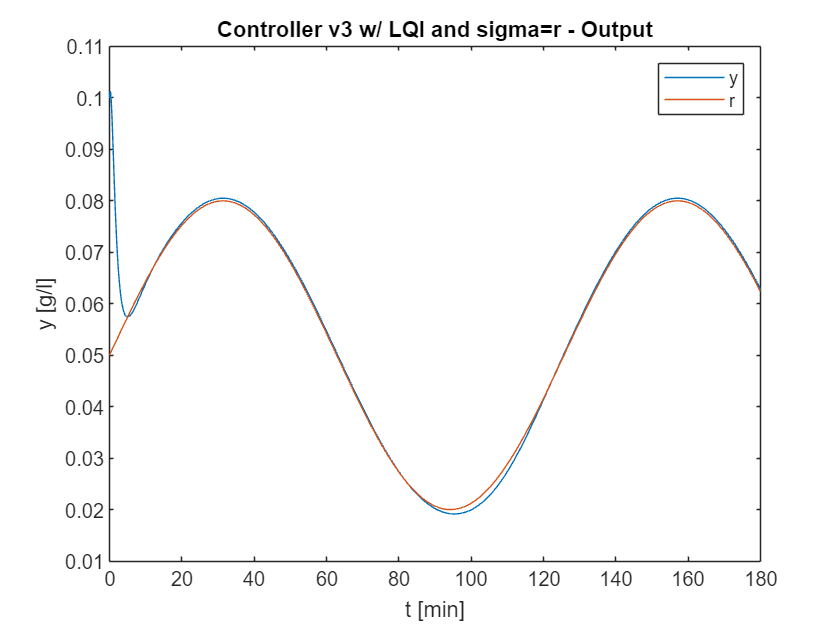

reference_selector=4;
simout = sim('v3_sim_lqi_sigma_r_time_variant.slx');
y = simout.y;
t = simout.t;
u = simout.u;
r = simout.r;
figure;
plot(t, y)
xlim([0,180])
title('Controller v3 w/ LQI and sigma=r - Output')
hold on
plot(t,r)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')